clearvars

Выбор файлов и импорт данных


Names = {'Bearing_2/50Hz_accelerometer.txt'};
Legend = {'Бороздка на внешнем кольце'};

Coef = 1000./[2.01, 1.99, 10.34, 10.2337];

N_signals = length(Names);
N = length(Names);
F_s = length(Names);
Time = length(Names);

for i=1:N_signals
    file = Names{i};
    headerLength = 19;
    fid = fopen(file);
    
    if fid == -1 
        error('File could not be opened, check name or path.')
    end
    
    header = cell(headerLength, 1);
    for j = 1:headerLength
        header{j} = fgetl(fid);
    end
    fclose(fid);
    fid = fopen(file);
    
    N(i) = str2double(header{3}(19:end));
    F_s(i) = str2double(header{8}(20:end))*1e3;
    Time(i) = str2double(header{9}(20:end));
end

time_temp = cell(N_signals, 1);
data_temp = cell(N_signals, 1);

F_s = max(F_s);
Time = linspace(0, max(Time), max(N));
Data = zeros(max(N), N_signals);

for i=1:N_signals
    file = Names{i};
    headerLength = 19;
    fid = fopen(file);
    
    if fid == -1 
        error('File could not be opened, check name or path.')
    end
    
    header = cell(headerLength, 1);
    for j = 1:headerLength
        header{j} = fgetl(fid);
    end
    fclose(fid);
    fid = fopen(file);

    numColumns = 1;
    data_temp{i} = cell2mat(textscan(fid, repmat('%f',1,numColumns), 'headerlines', headerLength));

    if max(N) == min(N)
        Data(:,i) = detrend(data_temp{i}*Coef(i));
    else
        time_temp{i} = linspace(0, str2double(header{9}(20:end)), N(i));
        Data(:,i) = detrend(interp1(time_temp{i}, data_temp{i}*Coef(i), Time, 'linear', 'extrap'));
    end
    fclose(fid);
end
N = max(N);

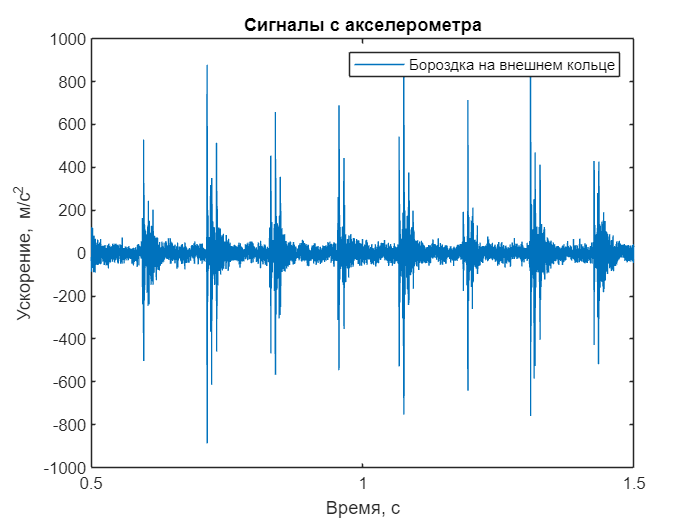

fc = 20; % Нижняя граница фильтра ВЧ
[b,a] = butter(4, fc/(F_s/2), 'high'); % Фильтр ВЧ

Data = filtfilt(b, a, Data);

plot(Time, Data)
xlim([0.5; 1.5])
xlabel('Время, с')
ylabel('Ускорение, м/с^2')
title('Сигналы с акселерометра')
legend(Legend)



Freq = F_s*(0:N/2)/N;
FFT_Data = FFT(Data);

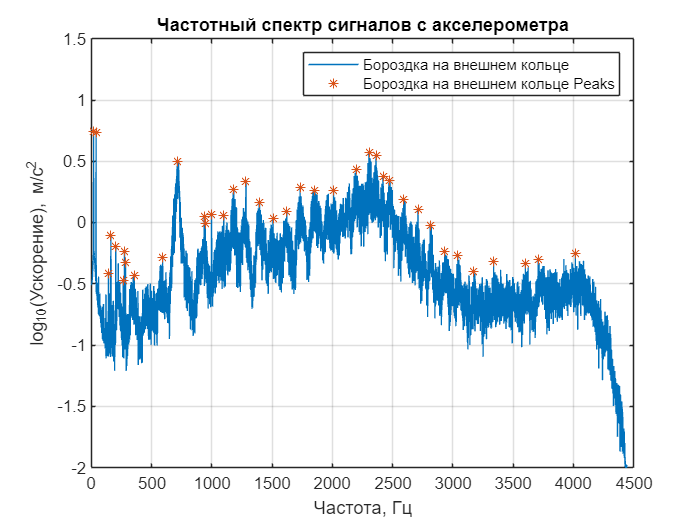


Window = 10;
Threshold = 0.5;
Peaks = Findpeaks(FFT_Data(round(Time(end)):end,:), Freq(round(Time(end)):end), Window, Threshold, Names);

Window = 3;
FFT_data_max = FFT_Data;
for j=1:N_signals
    for i=Window+1:floor(N/2)-Window
        FFT_data_max(i-Window, j) = max(FFT_Data(i-Window:i+Window, j));
    end
    FFT_data_max(:,j) = smooth(FFT_data_max(:,j), Window);
end

plot(Freq, log10(FFT_data_max))
hold on
for i=1:length(Peaks)
    plot(Peaks(i).Freq, Peaks(i).Amp, '*')
end
grid on
xlim([0; F_s/2])
ylim([-2; 1.5])
xlabel('Частота, Гц')
ylabel('log_{10}(Ускорение), м/с^2')
title('Частотный спектр сигналов с акселерометра')
legend([Legend, append(Legend, ' Peaks')])
hold off



N_b = 17; % количество тел вращения
B_d = 0.0072; % диаметр ролика
D1 = 0.0452; % диаметр наружного кольца
D2 = 0.0310; % диаметр внутреннего кольца
P_d = (D1+D2) / 2;
beta = 0; % Угол контакта (если замеры сделаны по приведенной схеме)

disp('РАЗМЕРЫ ПОДШИПНИКА:')

РАЗМЕРЫ ПОДШИПНИКА:


disp(['Количество роликов: ', num2str(N_b)])

Количество роликов: 17


disp(['Диаметр наружнего кольца: ', num2str(1e3*D1), ' мм'])

Диаметр наружнего кольца: 45.2 мм


disp(['Диаметр внутреннего кольца: ', num2str(1e3*D2), ' мм'])

Диаметр внутреннего кольца: 31 мм


disp(['Диаметр окружности качения роликов: ', num2str(1e3*P_d), ' мм'])

Диаметр окружности качения роликов: 38.1 мм


disp(['Диаметр роликов: ', num2str(1e3*B_d), ' мм'])

Диаметр роликов: 7.2 мм



f_0 = zeros(N_signals,1); % Частота вращения подшипника
for i=1:N_signals
    [~,ind_max] = max(Peaks(i).Amp);
    f_0(i) = Peaks(i).Freq(ind_max);
    %f_0(i) = min(Peaks(i).Freq);
end


f_BPFO = f_0*N_b/2*(1-B_d/P_d*cos(beta)); % Дефект внешнего кольца
f_BPFI = f_0*N_b/2*(1+B_d/P_d*cos(beta)); % Дефект внутреннего кольца
f_FTF = f_0/2*(1-B_d/P_d*cos(beta)); % Дефект сепаратора
f_BSF = f_0*P_d/B_d*(1-(B_d/P_d*cos(beta))^2); % Дефект тел качения

disp('---------------------------------')

---------------------------------


disp('ЧАСТОТЫ ХАРАКЕТНЫХ ДЕФЕКТОВ:')

ЧАСТОТЫ ХАРАКЕТНЫХ ДЕФЕКТОВ:


disp(['Частота дефекта внешнего кольца (f_BPFO): ', num2str(f_BPFO), ' Гц'])

Частота дефекта внешнего кольца (f_BPFO): 140.6325 Гц


disp(['Частота дефекта внутреннего кольца (f_BPFI): ', num2str(f_BPFI), ' Гц'])

Частота дефекта внутреннего кольца (f_BPFI): 206.17 Гц


disp(['Частота дефекта сепаратора (f_FTF): ', num2str(f_FTF), ' Гц'])

Частота дефекта сепаратора (f_FTF): 8.2725 Гц


disp(['Частота дефекта тел качения (f_BSF): ', num2str(f_BSF), ' Гц'])

Частота дефекта тел качения (f_BSF): 104.0956 Гц


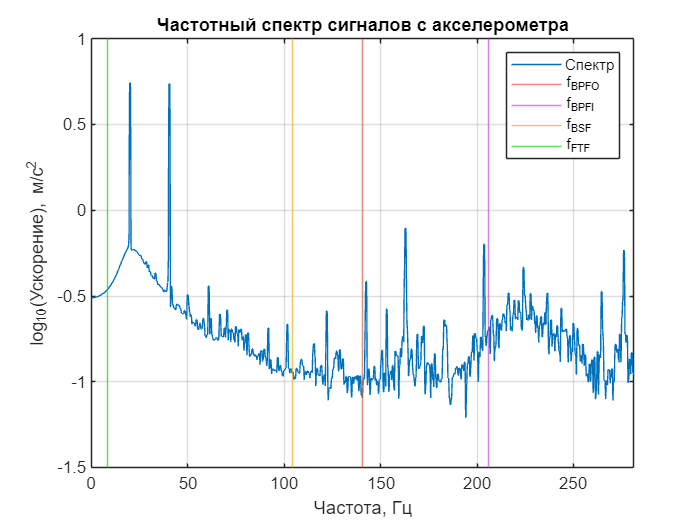


plot(Freq, log10(FFT_data_max))
grid on
xlim([0; f_BPFO*2])
xlabel('Частота, Гц')
ylabel('log_{10}(Ускорение), м/с^2')
title('Частотный спектр сигналов с акселерометра')
xline(f_BPFO, 'Color',[0.8210 0.3720 0.2560])
xline(f_BPFI, 'Color',[0.7940 0.2840 0.8560])
xline(f_BSF, 'Color',[0.9290 0.6940 0.1250])
xline(f_FTF, 'Color',[0.1290 0.7940 0.1250])
legend('Спектр', 'f_{BPFO}', 'f_{BPFI}', 'f_{BSF}', 'f_{FTF}')
hold off

### Спектр огибающей

Полосовой фильтр

fpass = [1500 2000];
fstop = [min(fpass)-200 max(fpass)+200];

[N_b, Wn] = buttord(fpass/(F_s/2), fstop/(F_s/2), 1, 60);
[b, a] = butter(N_b, Wn, 'bandpass');

%fvtool(b, a, 'Fs', F_s);

Data_filtered = filter(b, a, Data);

plot(Freq, log10(FFT(Data_filtered)))

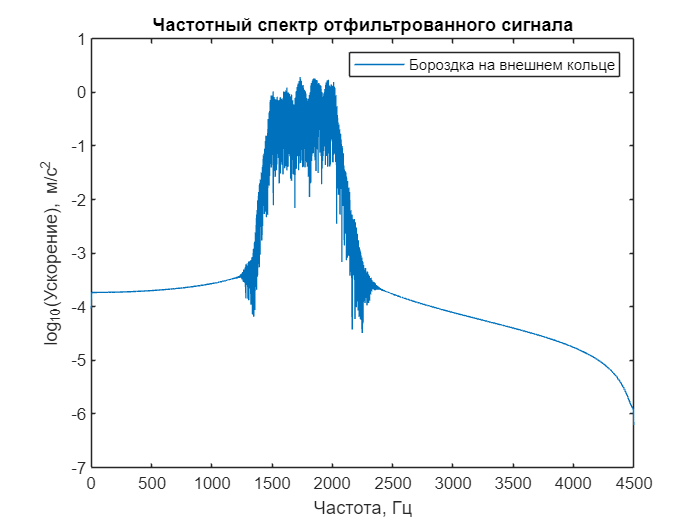

xlim([0; F_s/2])
xlabel('Частота, Гц')
ylabel('log_{10}(Ускорение), м/с^2')
title('Частотный спектр отфильтрованного сигнала')
legend(Legend)

Расчет огибающей

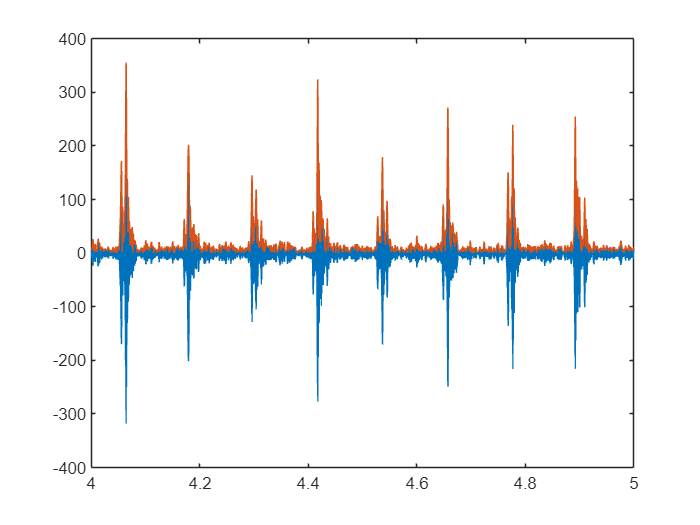

Data_envelope = envelope((Data_filtered), 200, 'analytic');

plot(Time, Data_filtered, Time, Data_envelope)
xlim([4; 5])

%ylim([-100; 100])


Низкочастотная фильтрация

[b,a] = butter(1, 200/(F_s/2), 'low'); % Фильтр ВЧ
Data_envelope = detrend(Data_envelope);
Data_envelope = filtfilt(b, a, Data_envelope);


Спектр огибающей


plot(Freq, log10(FFT(Data_envelope)))

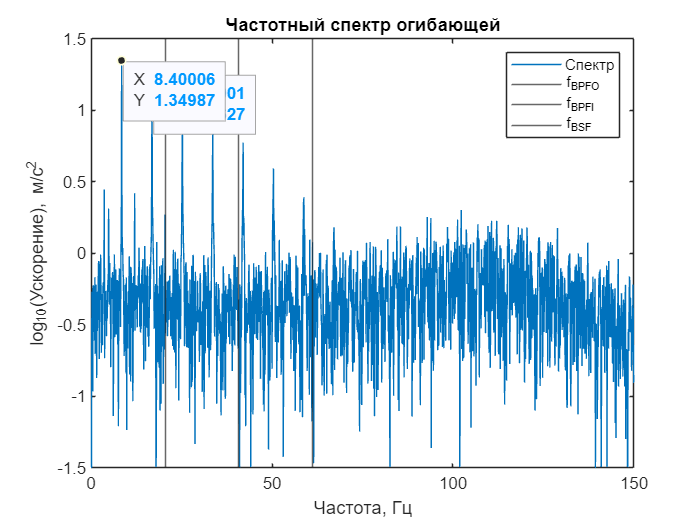

xlim([0; 150])
ylim([-1.5; 1.5])
xlabel('Частота, Гц')
ylabel('log_{10}(Ускорение), м/с^2')
title('Частотный спектр огибающей')
%xline([f_BPFO, 2*f_BPFO, 3*f_BPFO], 'Color',[0.8210 0.3720 0.2560])
%xline([f_BPFI, 2*f_BPFI, 3*f_BPFI], 'Color',[0.7940 0.2840 0.8560])
%xline([f_BSF, 2*f_BSF, 3*f_BSF], 'Color',[0.9290 0.6940 0.1250])
%xline([f_FTF, 2*f_FTF 3*f_FTF], 'Color',[0.1290 0.7940 0.1250])
xline([f_0, 2*f_0, 3*f_0])
legend('Спектр', 'f_{BPFO}', 'f_{BPFI}', 'f_{BSF}', 'f_{FTF}')

function [FFT] = FFT(Data_time)

    [N_row, N_column] = size(Data_time);

    for i=1:N_column
        FFT_Acceleration_filtered = fft(Data_time(:,i)); % Быстрое преобразование Фурье
        P2 = abs(FFT_Acceleration_filtered/N_row);
        P1_filtered = P2(1:N_row/2+1);
        P1_filtered(2:end-1) = 2*P1_filtered(2:end-1);
        if i == 1
            FFT = zeros(length(P1_filtered), N_column);
        end
        FFT(:,i) = P1_filtered;
    end
end

function [Peaks] = Findpeaks(Data, Freq_data, Window, Threshold, Names)
    
    [N_row, N_column] = size(Data);

    Name = string(Names);
    Peaks(N_column) = struct('Name', [], 'Freq', [], 'Amp', []);

    for i=1:N_column
        Peaks(i).Name = Name(i);
        Data_max = zeros(N_row, 1);
        Data_max(1:Window) = Data(1:Window, i);
        
        for j=Window+1:N_row
        
            Data_max(j) = max(Data(j-Window:j, i));
        end

        [Peaks(i).Amp, Peaks(i).Freq] = findpeaks(log10(Data_max), Freq_data, 'MinPeakProminence', Threshold);
    end
end

function [xCorr, lags, maxt, I] = Cohersion(Data, Ref)

    [xCorr,lags] = xcorr(Data, Ref);

    [~,I] = max(abs(xCorr));
    maxt = lags(I);
end